## **Assignment 3**

The action potentials emitted by neurons are usually seen as the most elementary processing unit in the brain. In rodents, for example, one can have neurons that fire their action potentials for very elementary features such as orientation, color and position of a visual stimulus, or more abstract ones, such as being or not in the nest and the animal position (as seen in assignment 1). 

The existence of such neuronal activity correlates leads to the idea that, somehow, the external stimulus are ‘encoded’ in the neuronal spikes, and we use them to perceive the world. With this in mind, we can think that a good way to investigate how this stimulus ‘encoding’ is done is trying to do the reverse operation. In order words, to use some measured neuronal activity to decode an external known feature/stimulus. That is what we are going to do in this assignment.

For that, we are going to use a Support Vector Machine classifier in Matlab (you will need the Statistical and the System identification toolboxes). 

## **Part 1 – Simulating our data**

To understand the initial steps of neuronal decoding we are first going to use some simulated data. Suppose that the neural activity (i.e., spikes) of an animal is modulated by a given stimulus. Because later on we are going to use some real data using sound stimulation, let’s consider that we have two sound stimuli and each sound is repeated 25 times. Each sound have a duration of 2 seconds and are presented in intervals of 5 seconds.

### Creating the neuron firing rate profiles

We will first modulate the activity of 20 neurons as an in-homogeneous Poisson process (as in Assignment 1). Each neuron will have it’s mean firing rate drawn from a random exponential distribution with mean 5. 

n_cells = 20;
n_stim_type = 2;

average_firing_rate = 5; % the peak firing rate, averaged across the population 
cell_rate_baseline = exprnd(average_firing_rate,[n_cells, 1]);

### Implementing changes in firing rate during stimulus

Also, the mean firing rate of each neuron will be modulated by a multiplicative factor during the stimuli presentation, drawn from a normal distribution with mean 1 and 0.5 std.

modulation = (1+ 0.5*randn(n_cells,1));

cell_rate_stim1 = cell_rate_baseline.*modulation;

To simplify, we are going to use opposite modulations for the different stimuli. In other words, if stim 1 is modulated by 1.2, stim 2 is modulated by 0.8.

cell_rate_stim2 = cell_rate_baseline.*(2-modulation);

cell_rate = zeros(n_cells,2,n_stim_type);

cell_rate(:,1,1) = cell_rate_baseline;
cell_rate(:,1,2) = cell_rate_baseline;

cell_rate(:,2,1) = cell_rate_stim1;
cell_rate(:,2,2) = cell_rate_stim2;


This is to guarantee that no neuron has a negative firing rate in case we get any modulation value higher than 2.

cell_rate(cell_rate(:)<0) = 0;


Let's look to how the firing rate of our neurons will behave:

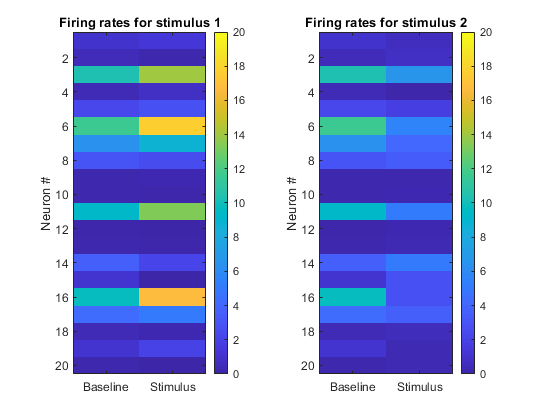


figure(1)
clf;
subplot(1,2,1)
imagesc(1:2,1:n_cells,squeeze(cell_rate(:,:,1)));

set(gca,'xtick',1:2,'xticklabel',{'Baseline', 'Stimulus'})
ylabel('Neuron #')
title('Firing rates for stimulus 1')
colorbar
caxis([0 20])

subplot(1,2,2)
imagesc(1:2,1:n_cells,squeeze(cell_rate(:,:,2)));

set(gca,'xtick',1:2,'xticklabel',{'Baseline', 'Stimulus'})
ylabel('Neuron #')
title('Firing rates for stimulus 2')
colorbar
caxis([0 20])

### Simulating stimulus


srate = 10000; % the sampling rate of our emulated recording system
noise_rate = 1; % we are going to add some spike noise non related to the task
n_stim = 100; % number of stimuli

stim_dur = 2; % stimulus duration (in seconds)
stim_interval = 5; % interval between stimuli (in seconds)

stim_times = 1:stim_interval:stim_interval*n_stim; % time of each stimulus (in seconds)
stim_type = [ones(1,n_stim/2) 2*ones(1,n_stim/2)]; % identity of each stimulus


ttime=max(stim_times)+stim_interval; % total recorded time
time = 0:1/srate:ttime; % time vector of the sampled times.

spktimes={};
for icell=1:n_cells

    % Creating the spikes with the baseline firing rate
    spikes = poissrnd(cell_rate(icell,1,1)/srate,[1,length(time)]);
    
    for itype = 1:n_stim_type
        % find the indexes of each of the stimulus
        idx = stim_type == itype;
        
        % for those indexes, get the stimulus start time
        for stim_start=stim_times(idx)
            
            % from the start of the stimulus until it's duration we use a
            % different firing rate for the poisson process, which depends
            % on the stimulus type.
            idx = (time>stim_start & time<=stim_start+stim_dur);
            spikes(idx) = poissrnd(cell_rate(icell,2,itype)/srate,[1,sum(idx)]);
        end        
    end
    
    % at last we add the spike noise
    spikes = spikes + poissrnd(noise_rate/srate,[1,length(time)]);
    
    idx = find(spikes>0);
    spktimes{icell} = time(idx);
end


Now we have some time series very similar to what we would get in a real experiment. The timestamps of each neuronal spikes (SPKTIMES), and the  stimuli time (STIM_TIMES) and type (STIM_TYPE). Let's save this data, and go on from the next script.


save('simulated_data1','spktimes','stim_type','stim_times','srate')

